# **Lista 1**

#### Universidade Tecnológica Federal do Paraná

#### Professor: Wellington José Corrêa

#### Cálculo Numérico

## **Introdução ao MATLAB**

Neste tutorial, estudaremos brevemente algumas características e funcionalidades do MATLAB. Para executar os comandos, apenas digite *Ctrl + Enter. *Aqui daremos

apenas um repasso de alguns importantes comandos.

### 1 Cálculando com o MATLAB

**Variáveis**

No Matlab, todos os resultados (números, vetores, matrizes, etc.) são armazenados em variáveis. Os nomes das variáveis devem começar com uma letra seguida de qualquer número de letras, dígitos ou *underscores*:

a = 3, b = 7, c = a + b

a = 3

b = 7

c = 10

d= a*b

d = 21

e= a/b

e = 0.4286

f=a+b+c;

Veja que o valor de f não foi exibido, pois o  uso de ; no final de um comando de atribuição inibe a apresentação do resultado.

Comentários (muito úteis em programação) são escritos após um %:

b = 5; % base
h = 7; % altura
A = b * h % Área do retângulo

A = 35

Potenciação, raiz quadrada e outras raízes:

 a = sqrt(5), b = a^2

a = 2.2361

b = 5.0000

 a = 7^(1/3), b = a^3

a = 1.9129

b = 7.0000

Por padrão o MATLAB devolve 4 casas depois da vírgula. Caso desejamos obter o valor de $a$ com 15 casas, temos o comando format long:

 format long
 a

a =    1.912931182772389


Para voltar ao padrão do software, basta utilizar o comando *format short*

 format short
 a

a = 1.9129

Valor absoluto, resto da divisão inteira: 

 n = abs(-500) % Valor absoluto

n = 500

 r = rem(n, 3) % resto da divisão inteira

r = 2

 s=sign(-30)

s = 1

Arredondamento:

x = sqrt(10)

x = 3.1623

a = floor(x) % arredonda para o inteiro inferior

a = 3

b = ceil(x) % arredonda para o inteiro superior

b = 4

c = round(x)  % arredonda para o inteiro mais próximo

c = 3

**Operações trigonométricas: **

O número $\pi$:

pi

ans = 3.1416

Seno, cosseno e tangente de um ângulo em radianos:

a = sin(pi/3), b = cos(pi/3), c = tan(pi/3)

a = 0.8660

b = 0.5000

c = 1.7321

Seno, cosseno e tangente de um ângulo em graus:

a = sind(60), b = cosd(60), c = tand(60)

a = 0.8660

b = 0.5000

c = 1.7321

Funções trigonométricas inversas

t1 = asin(sqrt(2)/2) % ângulo em radianos

t1 = 0.7854

t2 = asind(sqrt(2)/2)  % ângulo em graus

t2 = 45.0000

**Exponencial e Logaritmo**

Potência de base natural: $\mathrm{e}^x:$

exp(4)

ans = 54.5982

Logaritmos: $\ln\,x,\,\log_{10}\,x,\,\log_2\,x:$

log(5), log10(1000), log2(512)

ans = 1.6094

ans = 3

ans = 9

**Vetores e matrizes**

O Matlab opera com vetores e matrizes com facilidade. Um Vetor é definido por seus elementos: 

x = [1 2 3 4 5]

x =      1     2     3     4     5


Vetor definido por intervalo de valores:

y = 1 : 0.5 : 3 % vetor de valor inicial 1, espaçamento 0.5 e valor final 3.

y =     1.0000    1.5000    2.0000    2.5000    3.0000


Operações com o vetores:

x + y   % adição

ans =     2.0000    3.5000    5.0000    6.5000    8.0000


x .* y  % multiplicação elemento-elemento

ans =      1     3     6    10    15


x.^2   % potência dos elementos 

ans =      1     4     9    16    25


exp(y) % exponencial de cada elemento

ans =     2.7183    4.4817    7.3891   12.1825   20.0855


dot(x, y)  % produto escalar entre x e y

ans = 35

n = length(x) % tamanho do vetor

n = 5

A função *linspace* gera um vetor linha de pontos igualmente (e linearmente) espaçados:

linspace(0,1,6) %gera 6 pontos entre 1 e 2

ans =          0    0.2000    0.4000    0.6000    0.8000    1.0000


O operador **:** dado pelo comando $a:b$ gera um conjunto de pontos entre $a$ e $b$ de incremento unitário:

t=1:5 % espaçamento unitário entre 1 e 5.

t =      1     2     3     4     5


s=1:.5:3 % espaçamento de valor 0.5 entre 1 e 2.

s =     1.0000    1.5000    2.0000    2.5000    3.0000


u = 10:-1:5 % o incremento aqui vale -1 entre os valores 5 e 10.

u =     10     9     8     7     6     5


Matriz definida por seus elementos:

A = [-2 0 1; -2 -3 0; 3 -2 -2] % uma matriz 3x3

A =     -2     0     1
    -2    -3     0
     3    -2    -2


B = rand(3,3)   % matriz com elementos aleatórios 3X3

B =     0.8147    0.9134    0.2785
    0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575


A(2,:) % extrai a segunda linha de A

ans =     -2    -3     0


A(:,3) % extrai a terceira coluna de A

ans =      1
     0
    -2


Operações matriciais:

A+B % adição

ans =    -1.1853    0.9134    1.2785
   -1.0942   -2.3676    0.5469
    3.1270   -1.9025   -1.0425


A.*B % produto

ans =    -1.6294         0    0.2785
   -1.8116   -1.8971         0
    0.3810   -0.1951   -1.9150


det(A) % o determinante de A

ans = 1.0000

inv(A) % a matriz inversa da A

ans =     6.0000   -2.0000    3.0000
   -4.0000    1.0000   -2.0000
   13.0000   -4.0000    6.0000


A^2 % multiplicando matrizes: A * A

ans =      7    -2    -4
    10     9    -2
    -8    10     7


A.^2 % cada elemento de A ao quadrado

ans =      4     0     1
     4     9     0
     9     4     4


[l, c] = size(A) % número de linhas e colunas de A

l = 3

c = 3

Transposição de vetores e matrizes: 

A = [1 2 3; 4 5 6]; x = [2 4 6];
A' %Transposta de A

ans =      1     4
     2     5
     3     6


x'%Transposta do vetor x

ans =      2
     4
     6


Matrizes especiais:

B = zeros(3,2) % matriz de zeros

B =      0     0
     0     0
     0     0


W = ones(2,3) % matriz onde todas as entradas têm valor 1

W =      1     1     1
     1     1     1


I = eye(3) % matriz identidade

I =      1     0     0
     0     1     0
     0     0     1


rand(2,4) % matriz com elementos aleatórios

ans =     0.9649    0.9706    0.4854    0.1419
    0.1576    0.9572    0.8003    0.4218


Comandos úteis para vetores e matrizes:

x = [4 -2 5 0 -3]; % Um vetor x
M = max(x) % O maior elemento de x

M = 5

m = min(x) % O menor elemento de x

m = -3

S = sum(x) % A soma dos elementos de x

S = 4

Os comandos acima funcionam também para matrizes:

A = [1 5; 3 -4] % Uma matriz A

A =      1     5
     3    -4


M = max(A) % Os maiores elementos de cada coluna de A

M =      3     5


M = max(A') % Os maiores elementos de cada linha de A

M =      5     3


MM = max(max(A)) % O maior elemento de A

MM = 5

S = sum(A) % A soma dos elementos de cada coluna de A

S =      4     1


S = sum(sum(A)) % A soma de todos os elementos de A

S = 5

Os colchetes [  ] podem ser usados para justapor (concatenar) vetores ou matrizes:

A = [1 2; 4 5], b = [3; 6]

A =      1     2
     4     5


b =      3
     6


Ab = [A b] %Matriz ampliada de A e B

Ab =      1     2     3
     4     5     6


**Função anônima**

O comando @ define funções a partir de expressões algébricas. Por exemplo, desejamos definir a função

 
$$f(x)= \frac{1}{\sqrt{2\,\pi}}\,\mathrm{e}^{-0,5\,\cdot\,x^2}$$$


Usaremos o seguinte comando:

f = @(x) 1/sqrt(2*pi) * exp(-0.5 * x.^2)

f = function_handle with value:
    @(x)1/sqrt(2*pi)*exp(-0.5*x.^2)


a = f(0), b = f(1)

a = 0.3989

b = 0.2420

x1 = 0 : 5, d = f(x1)  %calcule a imagem de f(x) entre os valores inteiros de 0 a 5.

x1 =      0     1     2     3     4     5


d =     0.3989    0.2420    0.0540    0.0044    0.0001    0.0000


**Gráficos**

O Matlab possui uma variedade de comandos para produzir gráficos. O comando plot, para gráficos bidimensionais, é o mais simples deles. 

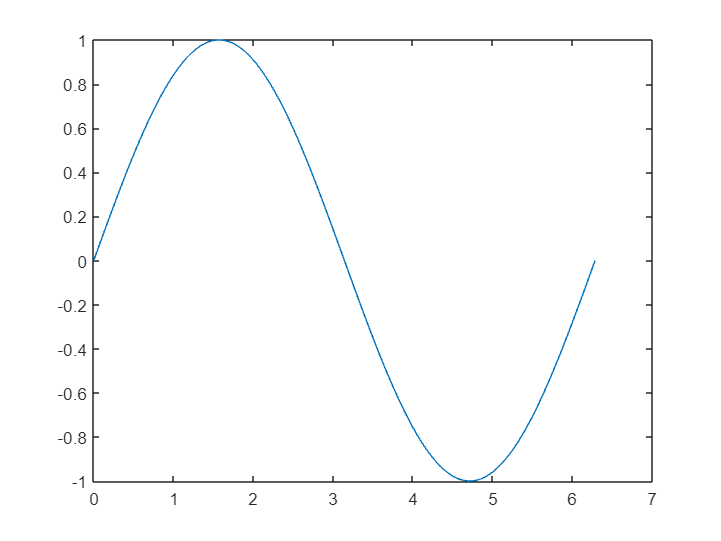

x = 0:pi/100:2*pi; % Cria um incremento de pi/100 no intervalo [0,2*pi]
y = sin(x);
plot(x,y)

Para plotar duas ou mais funções em um mesmo gráfico, usamos os comandos *hold on * e *hold off:*

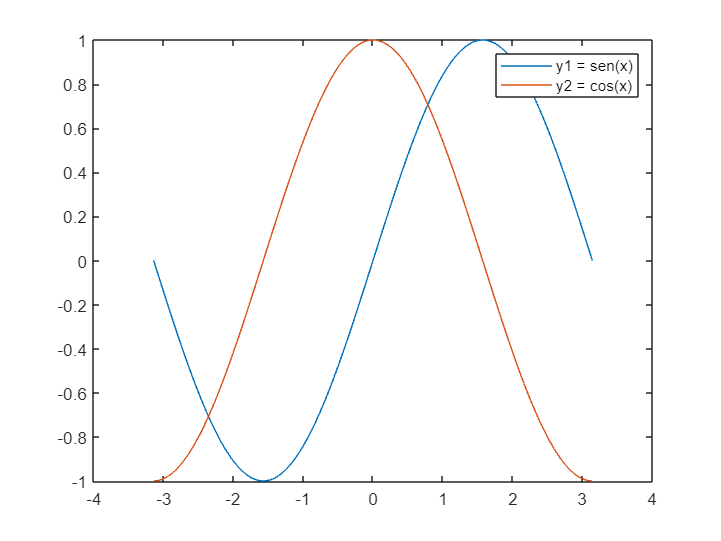

x = linspace(-pi,pi); %define intervalo de x para plotar no gráfico
y1 = sin(x); % define a função y1=sen(x);
plot(x,y1) % plota o gráfico da função y1=sen(x) com valores dados em x no início;

hold on   %manter o gráfico anterior
y2 = cos(x); %define a função y2=cos(x);
plot(x,y2) % plota o gráfico de x, y1 e y2;
legend('y1 = sen(x)','y2 = cos(x)')
hold off % finaliza  a junção de várias funções no mesmo gráfico; Isso é interessante quando se quer fazer um novo gráfico, mas com nova funções.

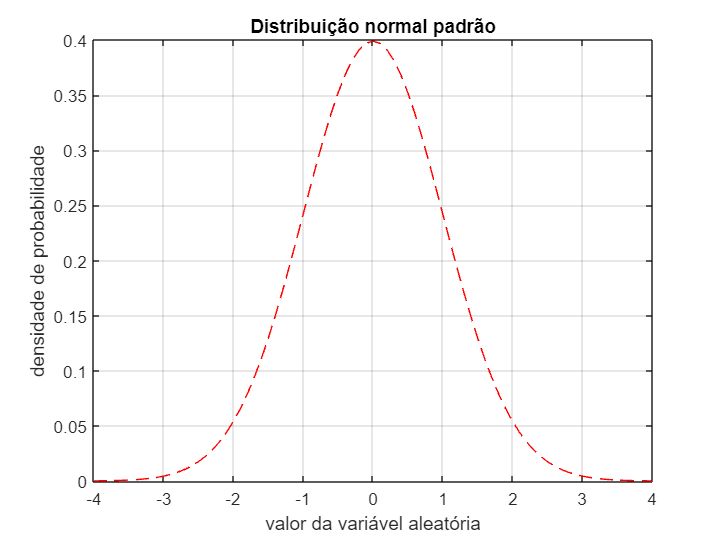

x = -4 : 0.1 : 4; % valores para z
 d = f(x); % valores para f(t)
 plot(x, d ,'r--') % gráfico com tracejado usando o comando 'r--'
 grid on % grade
 xlabel('valor da variável aleatória') % rótulo horiz.
 ylabel('densidade de probabilidade') % rótulo vert.
 title('Distribuição normal padrão') % título

Plotando dados:

x = [ 5 20 30 50 55 ]

x =      5    20    30    50    55


y = [ 0.08 0.015 0.009 0.006 0.0055]

y =     0.0800    0.0150    0.0090    0.0060    0.0055


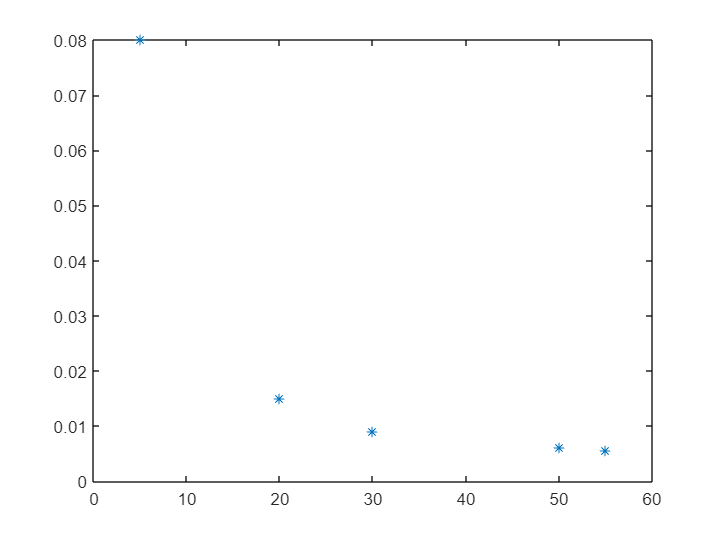

plot (x ,y , '* ')

## 2. Programando com o MATLAB

O Matlab permite a execução de conjuntos de comandos a partir de programas. Os programas são arquivos de texto escritos em um editor de programas e salvos em um arquivo de extensão "File.m". Falaremos disso em outra ocasião. Neste momento, vamos nos concentrar na estrutura lógica de um algoritmo. Um algoritmo é uma sequência determinada de passos para a resolução de algum problema. Do ponto de vista lógico, existem 3 estruturas que determinam quais, e como, os passos devem ser executados:

- **Sequência**:  determina qual passo deve ser executado antes de outro;

- **Decisão: **determina se um conjunto de passos deve ou não ser executado;

- **Repetição: **determina se (e quantas vezes) um conjunto de passos deve ser repetido

#### Estrutura de sequência

No Matlab os comandos são executados um de cada vez (não há processamento paralelo). E a sintaxe é simples: os comandos são escritos um a um de cima para baixo. Embora seja possível, não se recomenda escrever dois comando em uma mesma linha.

**Exemplo: **Determinação das raízes de uma equação quadrática $ax^2+bx+c=0$ com $a\neq\,0.$

clear all %limpa a memória
clc
a = 1

a = 1

b = 2

b = 2

c = -4

c = -4

d = b^2 - 4*a*c

d = 20

x1 = (-b + sqrt(d))/(2*a)

x1 = 1.2361

x2 = (-b - sqrt(d))/(2*a)

x2 = -3.2361

#### Estruturas de decisão

O Matlab possui duas estruturas de decisão básicas: if...else...end e outras funções dadas abaixo:

clear % limpa as variáveis
x=10;
if x>0
    disp("x é um valor positivo")
end

x é um valor positivo


Agora, modificaremos o o bloco, com o comando `elseif`, para imprimir a mensagem `"x é um valor negativo"`.

x = -28;
if x>0
    disp("x é um valor positivo")
elseif x<0
    disp("x é um valor negativo")
end

x é um valor negativo


Finalmente, pode ser usado o comando `else` para capturar qualquer caso omisso.

x = 0;
if x>0
    disp("x é um valor positivo")
elseif x<0
    disp("x é um valor negativo")
else
    disp("x é nulo")
end

x é nulo


#### Estrutura de repetição

Podemos fazer uma vetorização, isto é, repetir declarações um número específico de vezes. Para tanto, usaremos a estrutura de laço *for*:


i=0; % começa no zero
for t=0:0.5:2 % considera o intervalo de 0 a 2 com espaçamento 0.5
    i= i+1;  % adiciona o próximo inteiro
    y(i)=cos(t); % calcula o valor da sequência para cada valor de i, o valor de cos(t)
    display([t,y(i)]);
    
end

     0     1

    0.5000    0.8776

    1.0000    0.5403

    1.5000    0.0707

    2.0000   -0.4161



Veja na tabela acima que $y_0=cos(0), y_1=cos(0.5), y_2=cos(1.0), y_3=cos(1.5)$ e $y_5=cos(2.0)$

Exemplo: a soma dos 100 primeiros naturais:

n=100;
S = 0; % começa no zero
% O laço :
for i = 1: n % faz n vezes
S = S + i ; % adiciona o próximo inteiro
end % fim do laço
S

S = 5050

**Exemplo: **Calcule a tabuada do 6:

n=6;
T = zeros(10,1); %cria uma matriz coluna com 10 linhas nulas
for i = 1 : 10
T(i) = i * n;
display(T(i)); %exibe o valor da tabuada
end

     6

    12

    18

    24

    30

    36

    42

    48

    54

    60



O laço *while*  repete enquanto uma condição lógica for verdadeira. Um exemplo simples é o seguinte:

**Exemplo:** dado $x=8$, temos que exibir os valores de $x-3$ enquanto x for positivo. 

x=8;
while x>0 
x = x-3;
display(x) %apresenta os valores de x
end

x = 5

x = 2

x = -1